# s_opticsFresnel

This script implements the Fresnel equations to calculate the  lens reflection and transmission at the lens interface. The equations are described here:

The geometry of the incident plane wave (I), the refracted light (R) and the transmitted light (T).

The index of refraction of the medium on the left is n1 and on the right is n2.

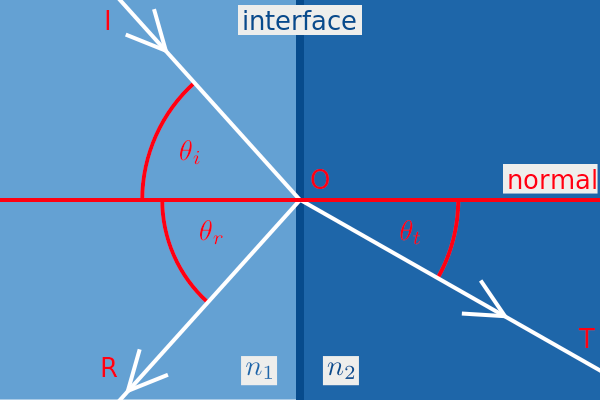

The Fresnel calculation is separated into the two different polarization angles, expressed classically as S and P.  For these calculations, we plot the average of the reflections from the two polarizations. That value is a good approximation for unpolarized light.

**Wandell, 2022**

## Definitions

The fraction of the incident [power](https://en.wikipedia.org/wiki/Power_(physics)) that is reflected from the interface is called the [*reflectance*](https://en.wikipedia.org/wiki/Reflectance) (or **reflectivity**, or **power reflection coefficient**) *R*, and the fraction that is refracted into the second medium is called the [*transmittance*](https://en.wikipedia.org/wiki/Transmittance) (or **transmissivity**, or **power transmission coefficient**) *T* . 

These values are measured at each side of the interface:  they do not account for attenuation as the light passes through an absorbing medium following transmission or reflection.[[2]](https://en.wikipedia.org/wiki/Fresnel_equations#cite_note-2)   In many applications, and as applied here, we assume no absorption (or almost none) in glass.

The reflected and transmitted light is related by


$$T=1-R$$


So, we only need to solve for one or the other. 

## Formula

There are two equations, one for each polarization, given by these two formulae ([from the wikipedia page](https://en.wikipedia.org/wiki/Fresnel_equations)).  

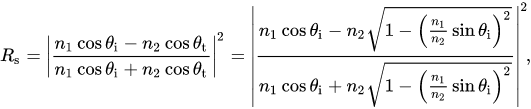

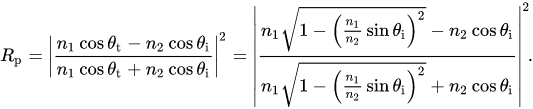

The advantage of the formula at the right is that we only need to know the incidence angle ( $\theta_i$ ). In the formula on the left, we need to know that angle and also the transmission angle ( $\theta_t$ ).  The formula on the right is derived from the one on the left using Snell's law.

We will calculate the average reflectance (or transmission) of the two polarization angles.

 
$$R_{E\;} =\frac{\left(R_s +R_p \right)}{2}$$


## Initialize ISETCam

ieInit;    % Set up ISETCam

### Example parameters

% Choose medium parameters and angles
n1 = 1.0;  % Air
n2 = 1.5;  % Glass
thetaIn = ((-25:25)/25)*(pi/2);   % Sample theta sub i from -pi/2 to pi/2

% Shortening the formula terms
ct = cos(thetaIn);
st = sin(thetaIn);
rad = (1 - (n1/n2)*st.^2).^0.5; 

% Calculate the reflectance
Rs = ( (n1*ct  - n2*rad) ./ (n1*ct  + n2*rad) ).^2;
Rp = ( (n1*rad - n2*ct)  ./ (n1*rad + n2*ct)  ).^2;
R = 0.5*(Rs + Rp);

## Plot the reflectance and transmittance as a function of incident angle

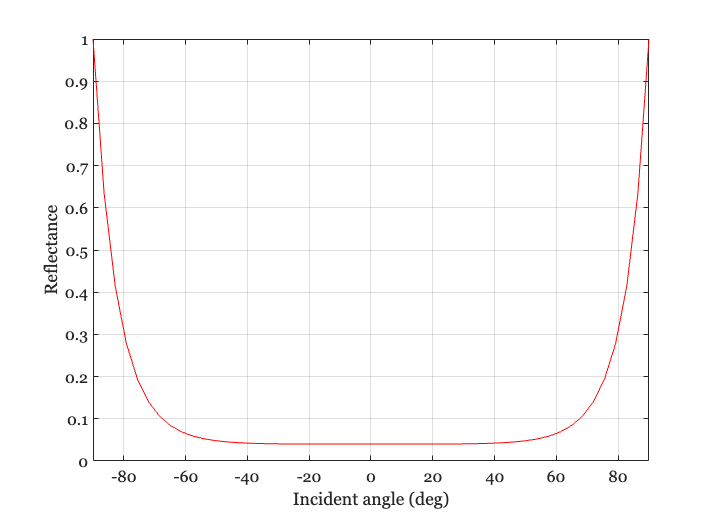

ieNewGraphWin;
plot(rad2deg(thetaIn),R);
grid on; xlabel('Incident angle (deg)'); ylabel('Reflectance');
set(gca,'xlim',[-90 90])

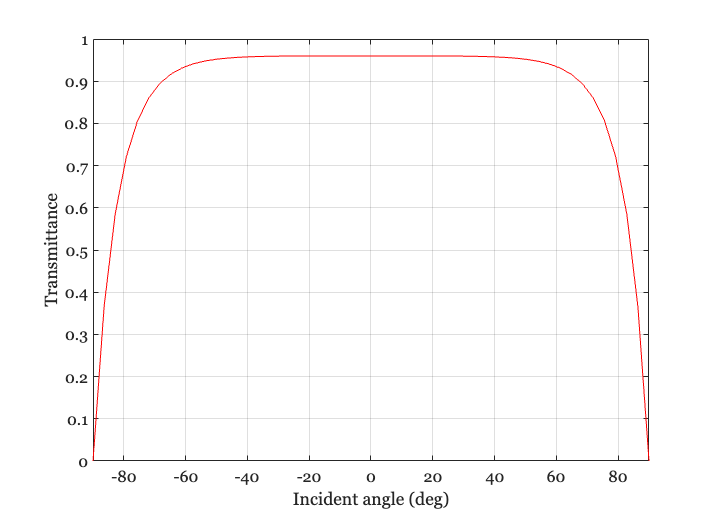

ieNewGraphWin;
plot(rad2deg(thetaIn),1-R);
grid on; xlabel('Incident angle (deg)'); ylabel('Transmittance');
set(gca,'xlim',[-90 90])

% The typicaly reflection amount is
fprintf('On axis reflection: %1.2f percent\n',100*min(R));

On axis reflection: 4.00 percent
